# Homework 4

% Question 1
% Parameters
mu = 0;
sigma = 1;

% Generate data
x = -4:0.01:4;
y = normpdf(x, mu, sigma);

% Plot distribution
figure;
plot(x, y);
hold on;

% Highlight the area of interest (Z < -1.35)
x_fill = -4:.01:-2;
y_fill = normpdf(x_fill, mu, sigma);
fill([x_fill, fliplr(x_fill)], [y_fill, zeros(size(y_fill))], 'r', 'FaceAlpha', 0.2);
x_fill = 2:0.01:4

x_fill =     2.0000    2.0100    2.0200    2.0300    2.0400    2.0500    2.0600    2.0700    2.0800    2.0900    2.1000    2.1100    2.1200    2.1300    2.1400    2.1500    2.1600    2.1700    2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900


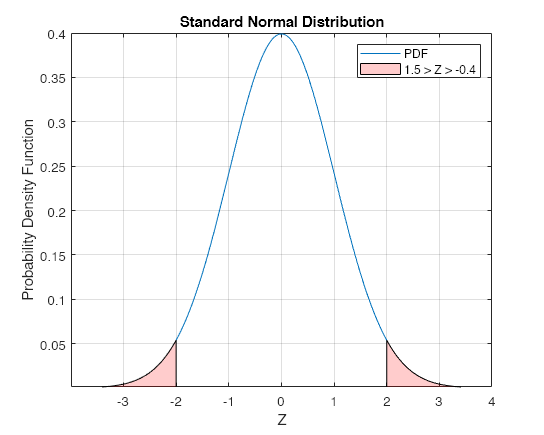

y_fill = normpdf(x_fill, mu, sigma);
fill([x_fill, fliplr(x_fill)], [y_fill, zeros(size(y_fill))], 'r', 'FaceAlpha', 0.2);




xlabel('Z');
ylabel('Probability Density Function');
title('Standard Normal Distribution');
legend('PDF', '1.5 > Z > -0.4');
grid on;


% Calculate the percentage using the CDF (cumulative distribution function)
percentage = (normcdf(-2, mu, sigma) * 100) * 2;
fprintf('The percentage of the distribution for |Z| > 2 is approximately %.2f%%\n', percentage);

The percentage of the distribution for |Z| > 2 is approximately 4.55%


mu = 4313;
sigma = 583;
cutoff_time = norminv(0.05, mu, sigma);
